## a)

f1 = @(x) exp(1)^x + 2^-x + 2*cos(x) - 6;
df1 = @(x) exp(1)^x - log(2) / 2^x - 2*sin(x);
f1a = 1;
f1b = 2;

f2 = @(x) log(x - 1) + cos(x - 1);
df2 = @(x) 1 / (x - 1) - sin(x - 1);
f2a = 1.3;
f2b = 2;

tol = 10^-6;
itmax = 100;

[r, iter] = biseccion(f1, f1a, f1b, tol, itmax);
fprintf('Método: Bisección');

Método: Bisección

fprintf('Iteraciones: %d', iter);

Iteraciones: 20

fprintf('Raíz: %.6f', r);

Raíz: 1.829383


[r, iter] = newtonra(f1, df1, f1a, tol, itmax);
fprintf('Método: Newton-Raphson');

Método: Newton-Raphson

fprintf('Iteraciones: %d', iter);

Iteraciones: 8

fprintf('Raíz: %.6f', r(iter));

Raíz: 1.829384


[r, iter] = secante(f1, f1a, f1b, tol, itmax);
fprintf('Método: Secante');

Método: Secante

fprintf('Iteraciones: %d', iter);

Iteraciones: 6

fprintf('Raíz: %.6f', r);

Raíz: 1.829384

## b)

f = @(x) nthroot(25, 3) - x;
fa = nthroot(25, 3) + 1;
fb = nthroot(25, 3) - 1;

[r, iter] = biseccion(f, fa, fb, tol, itmax);
fprintf('Método: Bisección');

Método: Bisección

fprintf('Iteraciones: %d', iter);

Iteraciones: 1

fprintf('Valor aproximado de 25^1/3: %.6f', r);

Valor aproximado de 25^1/3: 2.924018

## c)

f = @(x) 0.5*x^3 - 4*x^2 + 6*x -2.0;
df = @(x) 1.5*x^2 - 8*x + 6;

x0 = 4.2;
[r, iter] = newtonra(f, df, x0, tol, itmax);
fprintf('Raíz con %.2f: %.6f', x0, r(iter));

Raíz con 4.20: 0.474572

plot(1:iter, r);
hold on
plot(iter, r(iter), 'ro', 'MarkerSize', 10);

x0 = 4.43;
[r, iter] = newtonra(f, df, x0, tol, itmax);
fprintf('Raíz con %.2f: %.6f', x0, r(iter));

Raíz con 4.43: 0.474572

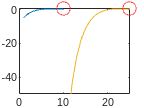

plot(1:iter, r);
plot(iter, r(iter), 'ro', 'MarkerSize', 10);
ylim([-50 1])

hold off

## d)

f = @(h) 12.4 - 10*(0.5*pi*1^2 - 1^2*asin(h/1) - h*(1^2 - h^2)^1/2);
df = @(h) 20*sqrt(1 - h^2);
a = 1;
b = 0;
tol = 10^-2;
itmax = 100;

[r, iter] = biseccion(f, a, b, tol, itmax);
fprintf('Método: Bisección');

Método: Bisección

fprintf('Iteraciones: %d', iter);

Iteraciones: 7

fprintf('Raíz: %.6f', r);

Raíz: 0.226562


[r, iter] = newtonra(f, df, b, tol, itmax);
fprintf('Método: Newton-Raphson');

Método: Newton-Raphson

fprintf('Iteraciones: %d', iter);

Iteraciones: 4

fprintf('Raíz: %.6f', r(iter));

Raíz: 0.221989


[r, iter] = secante(f, a, b, tol, itmax);
fprintf('Método: Secante');

Método: Secante

fprintf('Iteraciones: %d', iter);

Iteraciones: 3

fprintf('Raíz: %.6f', r);

Raíz: 0.222965